%Butterworth Filter Design
%Rough Working Program to design nice butterworth filters

Wp = 0.8/1;
Ws = 0.9/1;
Rp = 0.1;
Rs = 60;

[n,Wn] = buttord(Wp,Ws,Rp,Rs)

n = 13

Wn = 0.8324


d_sample_ratio_1= 10;
d_sample_ratio_2= 5;
d_sample_ratio= d_sample_ratio_1*d_sample_ratio_2;
t = (1:51200)*1/100; 

waveVertAcc = accZ;
waveVertAcc = waveVertAcc(1:51200);

[b, a] = butter(7, 0.5436)

b =     0.0262    0.1837    0.5511    0.9185    0.9185    0.5511    0.1837    0.0262


a =     1.0000    0.6055    1.0632    0.3851    0.2476    0.0464    0.0107    0.0006


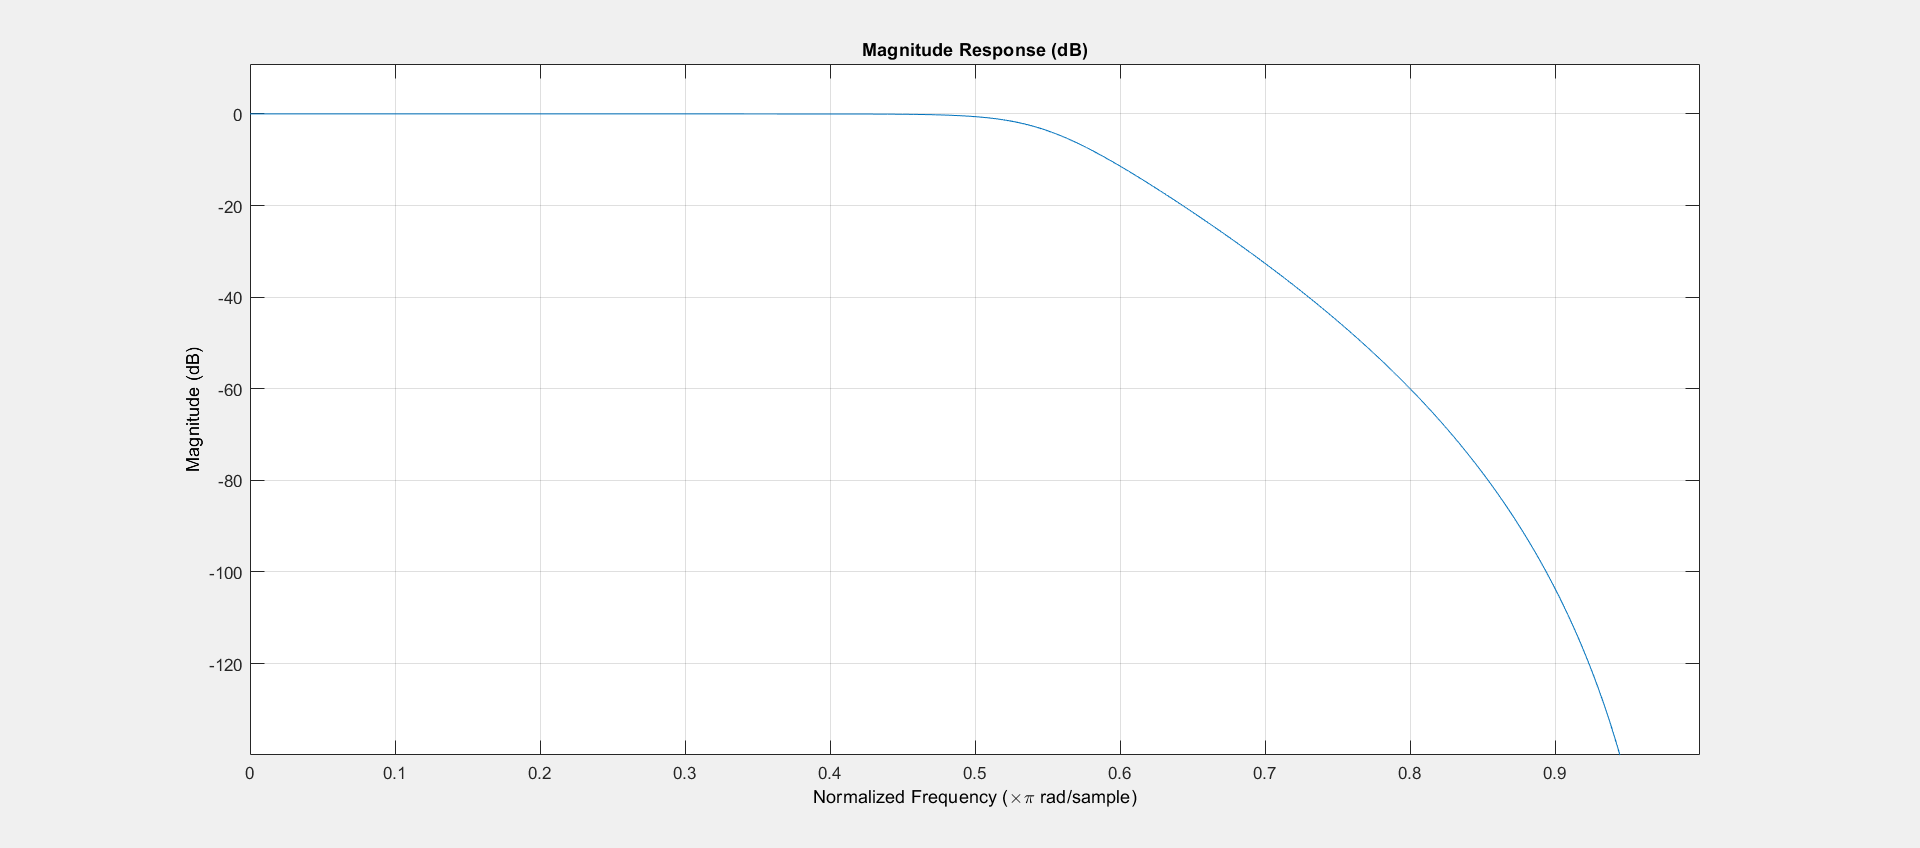

waveVertAcc = filter(b, a, waveVertAcc);
accLowPassTemp = downsample(waveVertAcc, d_sample_ratio_1);
t_temp = downsample(t, d_sample_ratio_1); 
    
%freqz(b, a, 512)
fvtool(b, a);

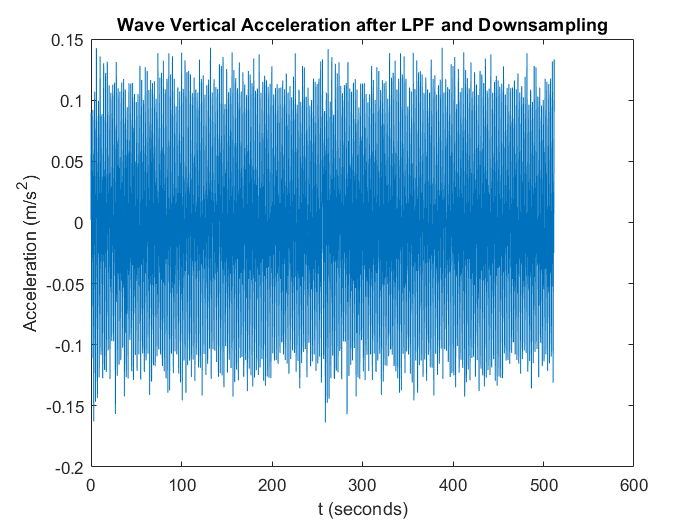


figure();
plot(t_temp, accLowPassTemp);
title('Wave Vertical Acceleration after LPF and Downsampling')
xlabel('t (seconds)')
ylabel('Acceleration (m/s^2)')


[b, a] = butter(5, 0.6419)

b =     0.1420    0.7098    1.4196    1.4196    0.7098    0.1420


a =     1.0000    1.3995    1.3220    0.6258    0.1756    0.0200


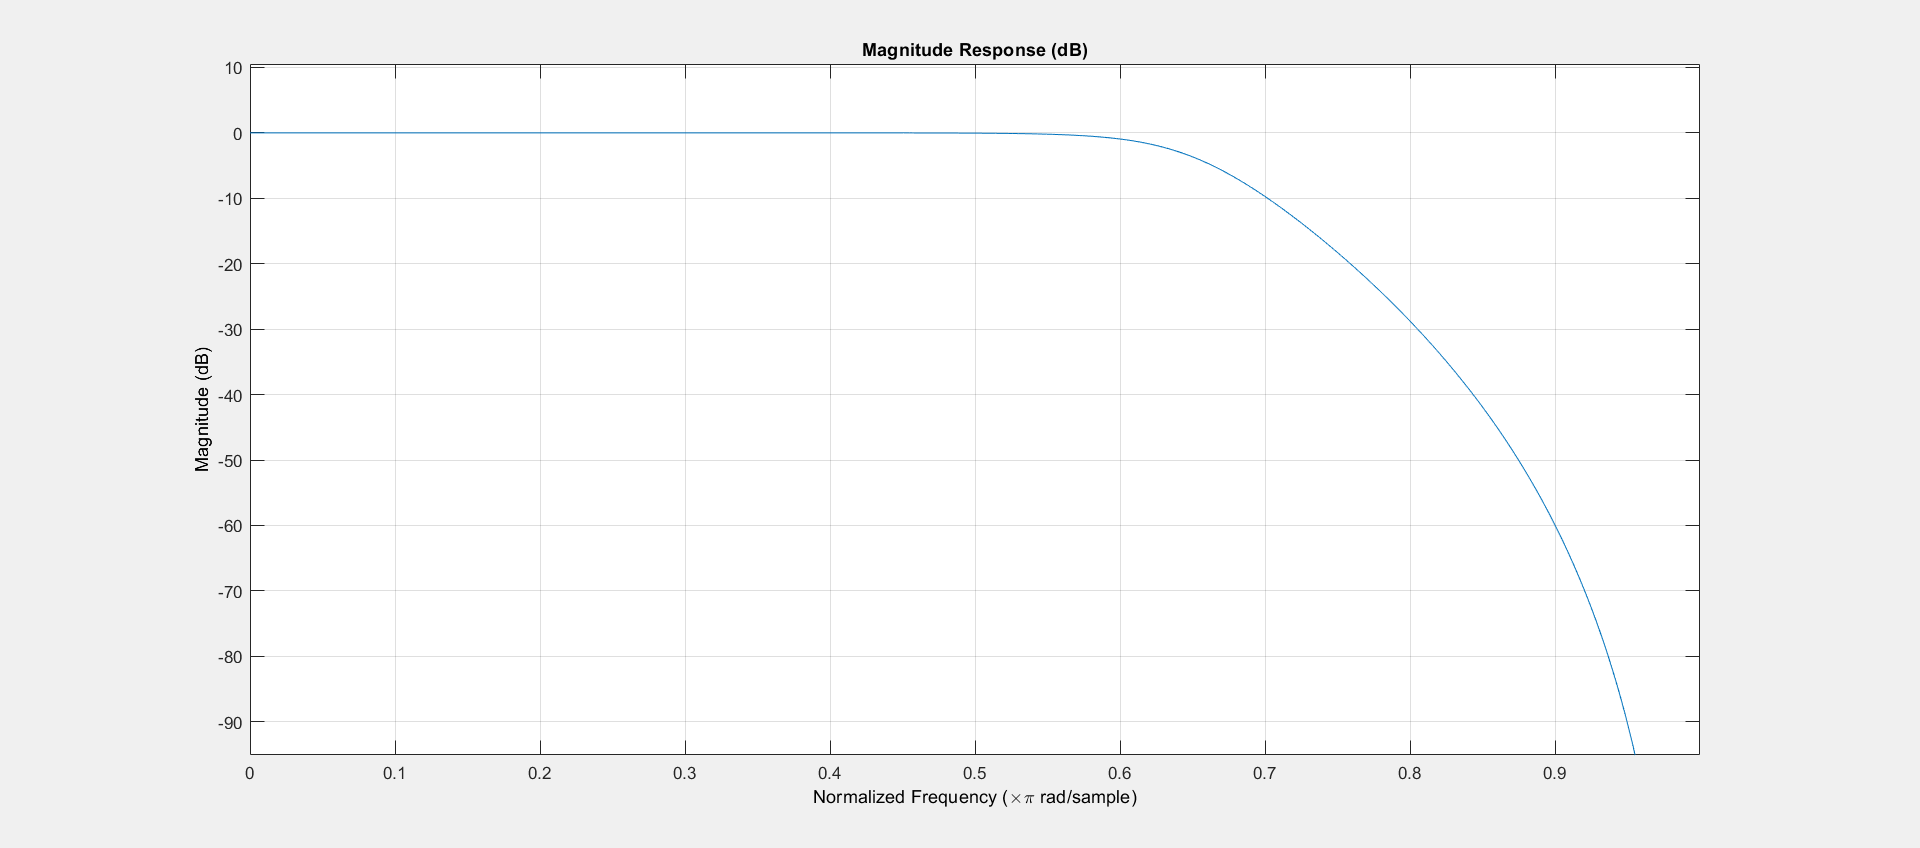

accLowPassTemp = filter(b, a, accLowPassTemp);
accLowPassTemp = downsample(accLowPassTemp, d_sample_ratio_2);
t_temp = downsample(t_temp, d_sample_ratio_2); 
    
%freqz(b, a, 512)
fvtool(b, a);

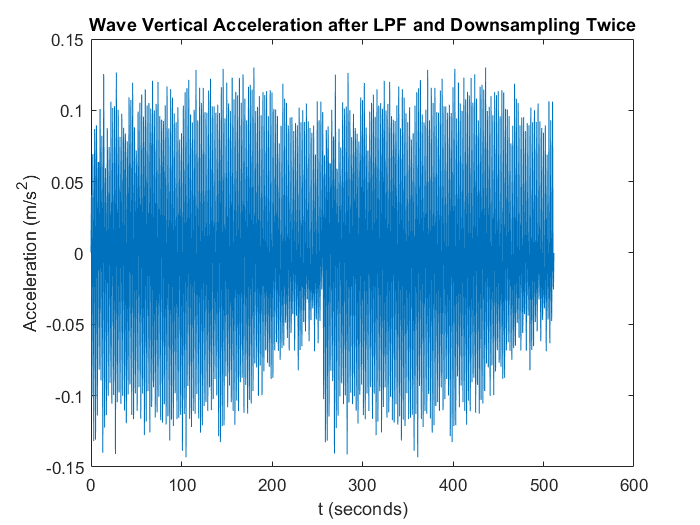


figure();
plot(t_temp, accLowPassTemp);
title('Wave Vertical Acceleration after LPF and Downsampling Twice')
xlabel('t (seconds)')
ylabel('Acceleration (m/s^2)')